SnS Lab 02 Report

Task 1:

Part 1:

a = complex(15.5, 3.175);
real(a);
imag(a);
conj(a);
phase = angle(a);
magnitude = abs(a);

Part 2:

b =complex(5*cosd(45), 5*sind(45));
real(b);
imag(b);
conj(b);
phase = angle(b);
magnitude = abs(b);

Task 2: Part (A)

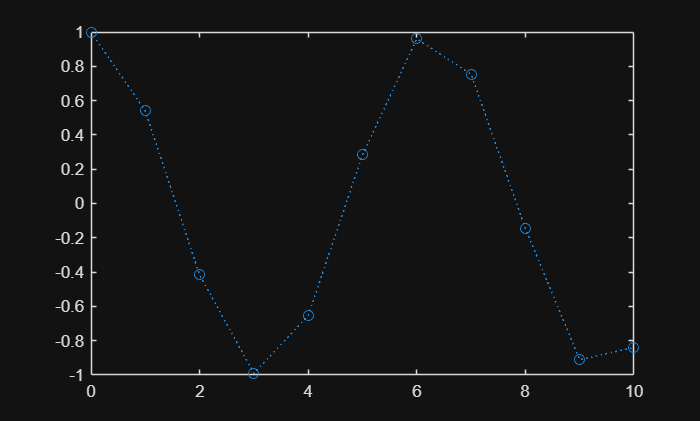

% TRY 1
n = 0:10;	% Discrete-time n is defined which goes from 0 to 10 in unity sampling interval. 
y1 = cos(n); 	% A sinusoidal function y[n] is defined attaining values -1≤y[n]≤1.
figure; 
plot(n, y1, ':o');	% A continuous-time graphical plot of the signal y[n] where circular markers are used to represent values connected with a dotted line. 

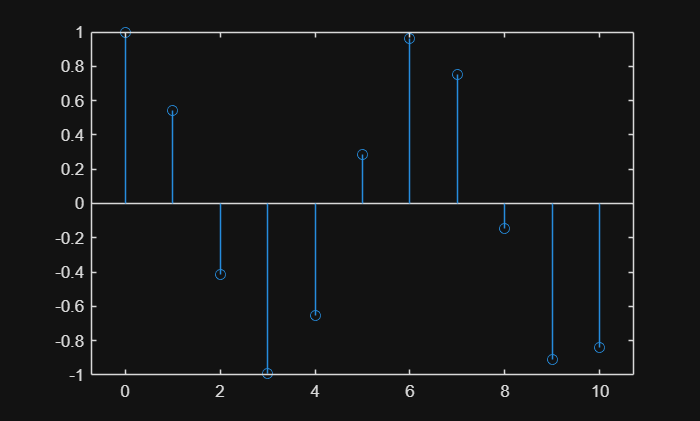

figure; 
stem(n, y1);

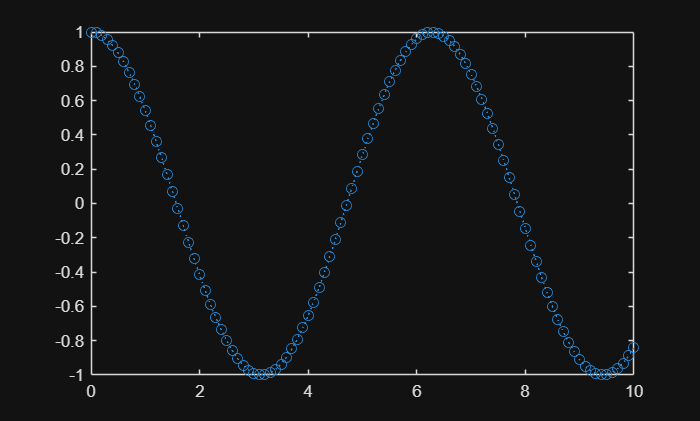


% TRY 2
Ts = 0.1;	% Defining sampling time, the time interval between two consecutive samples
Fs = 1/Ts;	% Defining sampling frequency, the number of samples per second
t = 0:Ts:10;	% Defining time span	
y2 = cos(t); 	% Obtaining a discrete-time signal
figure; 	% Using subplots to depict two plots in one figure
plot(t, y2, ':o'); 	

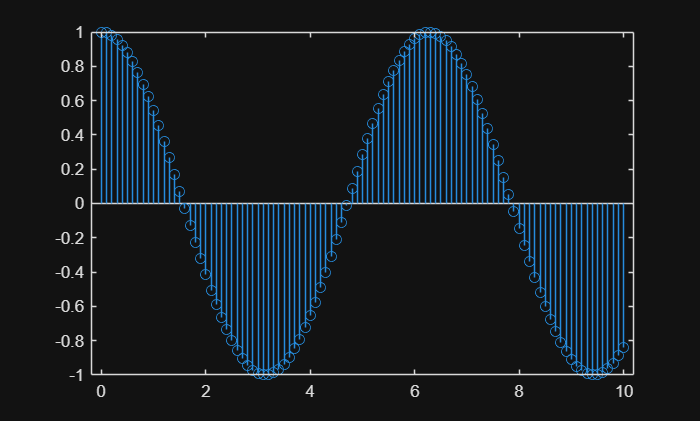

stem(t, y2);

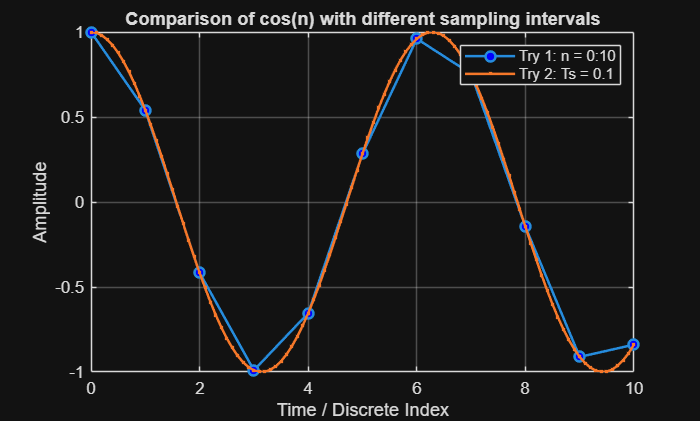


% comparing both graphs:
figure;
plot(n, y1, 'o-', 'LineWidth', 1.5, 'MarkerFaceColor','b'); 
hold on; 
plot(t, y2, '.-', 'LineWidth', 1.5, 'MarkerFaceColor','r');            
hold off;

% Adding labels.
title('Comparison of cos(n) with different sampling intervals');
xlabel('Time / Discrete Index');
ylabel('Amplitude');
legend('Try 1: n = 0:10', 'Try 2: Ts = 0.1');
grid on;

Comparing Results:

- Try 1 has fewer samples the signal looks “jumpy” or discrete. It does not capture rapid changes.

- Try 2 has more samples the signal looks smoother and closer to the continuous cosine curve. As more points are plotted, it captures more levels.

TASK 2: Part (B)

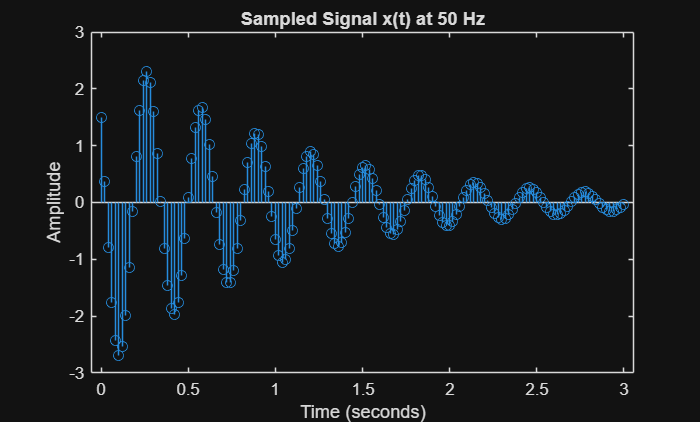

Fs = 50;           % Sampling frequency
Ts = 1/Fs;         % Sampling time
t = 0:Ts:3;        % Time 
x = 3 * exp(-t) .* cos(20*t + pi/3); % Function

figure;
stem(t, x);   
title('Sampled Signal x(t) at 50 Hz');
xlabel('Time (seconds)');
ylabel('Amplitude');

TRY 3:

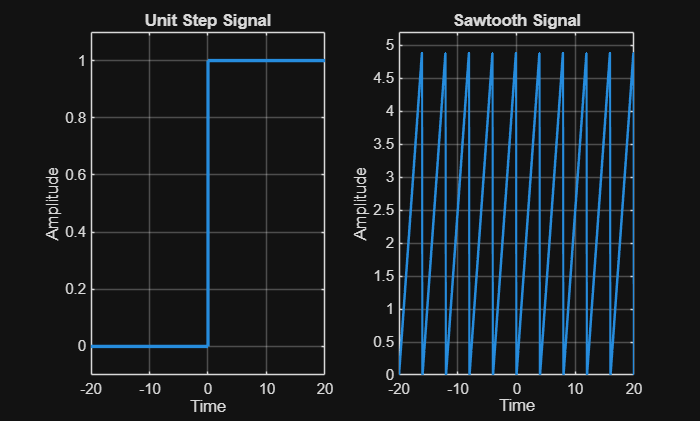


% time vector
t = -20:0.1:20; 

z = (t >= 0);    % Returns 1 when t>=0, 0 otherwise

T = 4;          
y = mod(t, T);  
y = y * (5/T);   

figure;

% Step signal
subplot(1,2,1);
stairs(t, z, 'LineWidth', 2);
title('Unit Step Signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 -0.1 1.1]);
grid on;

% Sawtooth signal
subplot(1,2,2);
plot(t, y, 'LineWidth', 1.5);
title('Sawtooth Signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 5.2]);  % Matches your original axis
grid on;

TASK 3:

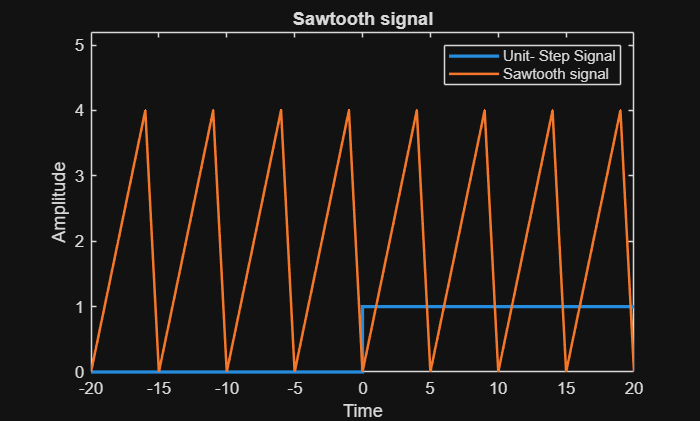

clc; clear
t = -20:1:20;
y = mod(t,5); 
z = (t>=0); 
figure;
stairs(t,z,'linewidth',2)			
title('Unit-step signal');
xlabel('Time');
ylabel('Amplitude');				
axis([-20 20 0 1.1]);
hold on
plot(t,y,'linewidth',1.5)
title('Sawtooth signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 5.2])
legend('Unit- Step Signal', 'Sawtooth signal')

TASK 4:

%% time vector
t = 0:0.005:5;      
L = length(t);   

%% two sinusoids
f1 = 1;          
f2 = 10;             

xt1 = sin(2*pi*f1*t); 
xt2 = sin(2*pi*f2*t);

%% noise
noise = randn(1, L); 
noise_new = noise*0.2

noise_new =     0.0187    0.3160    0.0490   -0.2041    0.2256    0.4465   -0.1548   -0.2003    0.2277   -0.0048   -0.2728    0.2473   -0.0308   -0.1590   -0.1163   -0.0995    0.1875   -0.2311    0.0938    0.2009   -0.1720    0.0669   -0.3307    0.1394   -0.2244    0.1613    0.0867   -0.0823   -0.2960    0.2663    0.0305    0.3355    0.0017   -0.3557    0.3380   -0.0583    0.1849   -0.1444    0.1224    0.1670    0.2026    0.0998   -0.0082    0.0289    0.0605   -0.1477    0.1101   -0.2129   -0.3811    0.0333


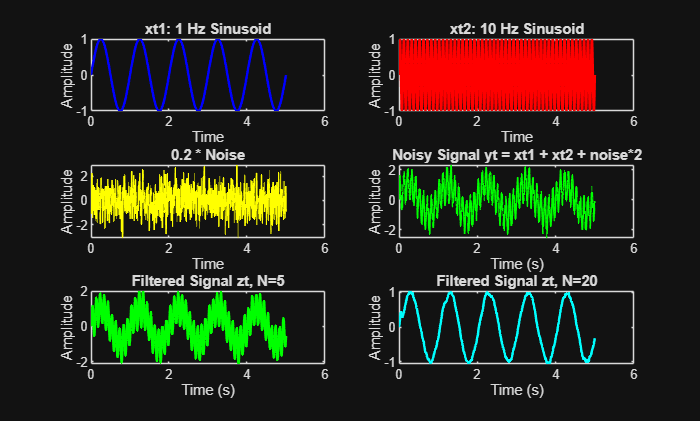


%%Combine signals
yt = xt1 + xt2 + noise_new;

%% Applying averaging filter
N1 = 5;               
N2 = 20;            

zt1 = filter(ones(1,N1)/N1, 1, yt);   % N=5
zt2 = filter(ones(1,N2)/N2, 1, yt);   %  N=20


figure;

% Plot 1: xt1
subplot(3,2,1);
plot(t, xt1, 'b', 'LineWidth', 1.5);
title('xt1: 1 Hz Sinusoid');
xlabel('Time');
ylabel('Amplitude');

% Plot 2: xt2
subplot(3,2,2);
plot(t, xt2, 'r', 'LineWidth', 1.5);
title('xt2: 10 Hz Sinusoid');
xlabel('Time');
ylabel('Amplitude');

% Plot 3: Noise
subplot(3,2,3);
plot(t, noise, 'y', 'LineWidth', 1);
title('0.2 * Noise');
xlabel('Time');
ylabel('Amplitude');

% Plot 4: Noisy signal yt
subplot(3,2,4);
plot(t, yt, 'g', 'LineWidth', 1);
title('Noisy Signal yt = xt1 + xt2 + noise*2');
xlabel('Time');
ylabel('Amplitude');

% Plot 5: Filtered signal (N=5)
subplot(3,2,5);
plot(t, zt1, 'g', 'LineWidth', 1.5);
title('Filtered Signal zt, N=5');
xlabel('Time');
ylabel('Amplitude');

% Plot 6: Filtered signal (N=20)
subplot(3,2,6);
plot(t, zt2, 'c', 'LineWidth', 1.5);
title('Filtered Signal zt, N=20');
xlabel('Time');
ylabel('Amplitude');

POST LAB:

TASK 5:

Part a:

theta1 = 85.5 * pi/180;

z1 = 10.09 + 55.3i + 20*(cos(theta1) + 1j*sin(theta1));

real_z1 = real(z1)

real_z1 = 11.6592

imag_z1 = imag(z1)

imag_z1 = 75.2383

conj_z1 = conj(z1)

conj_z1 = 11.6592 -75.2383i

phase_z1 = angle(z1)*180/pi

phase_z1 = 81.1913

mag_z1 = abs(z1)

mag_z1 = 76.1364

Part b:

theta2 = 10 * pi/180;

z2 = 15*(cos(theta2) + 1j*sin(theta2)) - (4 + 10i);

real_z2 = real(z2)

real_z2 = 10.7721

imag_z2 = imag(z2)

imag_z2 = -7.3953

conj_z2 = conj(z2)

conj_z2 = 10.7721 + 7.3953i

phase_z2 = angle(z2)*180/pi

phase_z2 = -34.4704

mag_z2 = abs(z2)

mag_z2 = 13.0663

Part 2: Plot Unit Ramp and Unit Impulse function:

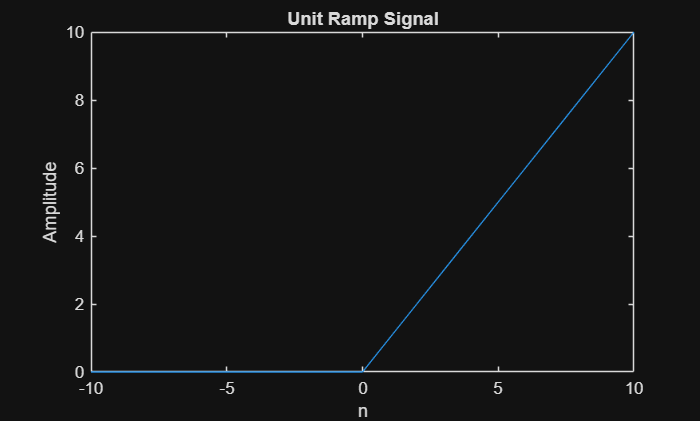

n = -10:10;
r = n .* (n >= 0);

% Ramp Signal
figure
plot(n, r)
xlabel('n')
ylabel('Amplitude')
title('Unit Ramp Signal')

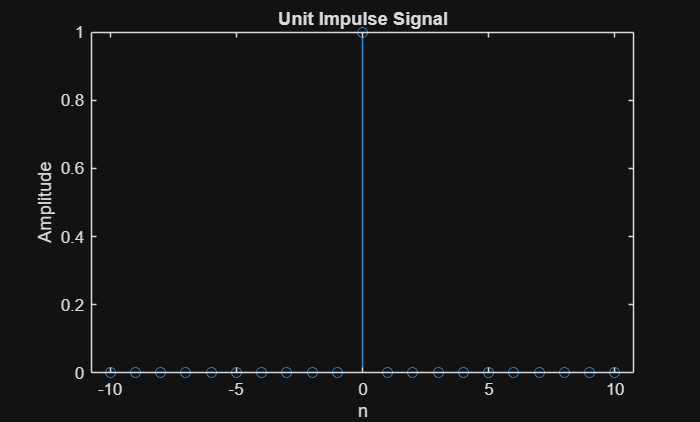


% Impulse Function
imp =(n == 0);
figure
stem(n, imp)
xlabel('n')
ylabel('Amplitude')
title('Unit Impulse Signal')

Task 6: Amplitude Modulation 

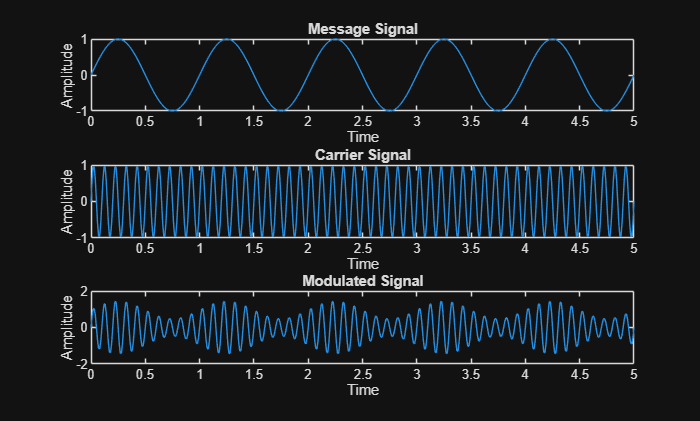

% Parameters
Am = 1;
Ac = 1;
fm = 1;
fc = 10;
mu = 0.5;
t = 0:0.01:5;

% Message signal
m = Am * sin(2*pi*fm*t);

% Carrier signal
c = Ac * sin(2*pi*fc*t);

% modulated signal
s = (1 + mu*m) .* c;

figure
subplot(3,1,1)
plot(t, m)
xlabel('Time')
ylabel('Amplitude')
title('Message Signal')

subplot(3,1,2)
plot(t, c)
xlabel('Time')
ylabel('Amplitude')
title('Carrier Signal')

subplot(3,1,3)
plot(t, s)
xlabel('Time')
ylabel('Amplitude')
title('Modulated Signal')